% Niranjan Mathirajan, Owen Davis
% December 12, 2025
% Phased Array Spacing Playground
% Source 1: https://innovationspace.ansys.com/courses/wp-content/uploads/sites/5/2022/07/AntennaArrays_04ManipulatingtheArrayFactor.pdf
% Source 2: https://www.antenna-theory.com/arrays/arrayfactor.php
% Source 3: https://www.antenna-theory.com/definitions/wavevector.php


% Some notes about the simulation:
% the phase factor should always assume ideal spacing, as the computer
% doesn't know about the error in spacing. This is why the simulation and
% calculation's spacing don't incorporate the actual spacing, rather the
% ideal
%
% The expected calculation should never use the actual spacing, just ideal
% and error. The whole point is that the expected value incorporates the
% ideal distribution of dx_error (uniform), so that we can calculate the
% true error.
clc;

% -- constants --
T = 5000; % number of trials performed
f = 5e6; % frequency of antenna (Hz)
c = 3e8; % speed of light (m/s)
lambda = c/f; % wavelength (m)
k = 2 * pi/lambda; % 1-D wave vector, see source (3) (rad/m)
nTheta = 180;
theta = linspace(-pi/2, pi/2, nTheta); % range of angles the array "sees"

% -- array parameters --
N = 15; % number of antennas
steerAngle = 51 * pi/180; % steering angle of array
dx_ideal = .25 * lambda; % expected distance between antennas
dx_error = 0.05* lambda; % max variation in spacing
measure_angle_deg = 30; % angle we measure AF at (range from 1 to 90)
measure_angle_rad = measure_angle_deg * 2*pi / 360;
phase = -k * dx_ideal * cos(steerAngle); % term added to each AF to aim beam


% --- Monte Carlo Simulation ---
simulated_average = zeros(T,1);
rng(58);
for i = 1:T
    AF = zeros(nTheta,1);
    % --- get position errors (non-cumulative) ---
    dx_actual = zeros(N,1);
    for n = 1:N
        dx_actual(n) = -dx_error + 2*dx_error*rand();
    end
    
    % --- get Array Factor for every angle
    for t = 1:nTheta
        for n = 1:N
            % AF equation from source (1):
            main_term = k*cos(theta(t))*((n-1)*dx_ideal + dx_actual(n));
            phase_term = -(n-1)*k*dx_ideal*cos(steerAngle);
            AF(t) = AF(t) + exp(1j*(main_term + phase_term));
        end
    end
    simulated_average(i) = AF(measure_angle_deg+90)/N;
end

sim_mean = abs(mean(simulated_average));

% --- Expected calculation ---

E = 0;
for n = 1:N
    m = n-1;
    % these terms were pulled out of the array factor, should match
    % previous.
    main_term = exp(1j*k*m*cos(measure_angle_rad)*dx_ideal);
    phase_term = exp(-1j*k*m*dx_ideal*cos(steerAngle));
    random_variable = (exp(1j*k*cos(measure_angle_rad)*dx_error) ...
            - exp(1j*k*cos(measure_angle_rad)*-1*dx_error))/(1j*k*cos(measure_angle_rad)*2*dx_error);
    E = E + (main_term * phase_term * random_variable);
end
analytic_mean = abs(E)/N;
analytic_mean_complex = E/N;

E_2 = 0;
for n= 1:N
    for m = 1:N
        main_term = exp(1j*k*dx_ideal*cos(measure_angle_rad)*(n-m));
        phase_term = exp(-1j*k*dx_ideal*cos(steerAngle)*(n-m));
        if n == m
            random_variable = 1;
        else
            random_variable_n = (exp(1j*k*cos(measure_angle_rad)*dx_error) ...
            - exp(1j*k*cos(measure_angle_rad)*-1*dx_error))/(1j*k*cos(measure_angle_rad)*2*dx_error);
            random_variable_m = (exp(-1j*k*cos(measure_angle_rad)*dx_error) ...
            - exp(1j*k*cos(measure_angle_rad)*dx_error))/(-1j*k*cos(measure_angle_rad)*2*dx_error);

            random_variable = random_variable_n*random_variable_m;
        end

        E_2 = E_2 + (main_term * phase_term * random_variable);
    end
end

analytic_var = (abs(E_2))/N^2 - abs(E/N)^2;
sim_var = var(simulated_average);

variance_perc_error = abs(sim_var - analytic_var)*100/analytic_var;
expected_perc_error = abs(sim_mean - analytic_mean)*100/analytic_mean;

fprintf(['Analytical Expected Value: %.4f | Variance: %.6f\n' ...
    'Simulated  Expected Value: %.4f | Variance: %.6f\n' ...
    'Percent error:\n' ...
    'Expected: %.2f%% | Variance: %.2f%%'], analytic_mean, analytic_var, sim_mean, var(simulated_average), expected_perc_error, variance_perc_error );

Analytical Expected Value: 0.1232 | Variance: 0.001629
Simulated  Expected Value: 0.1100 | Variance: 0.001632
Percent error:
Expected: 10.69% | Variance: 0.19%

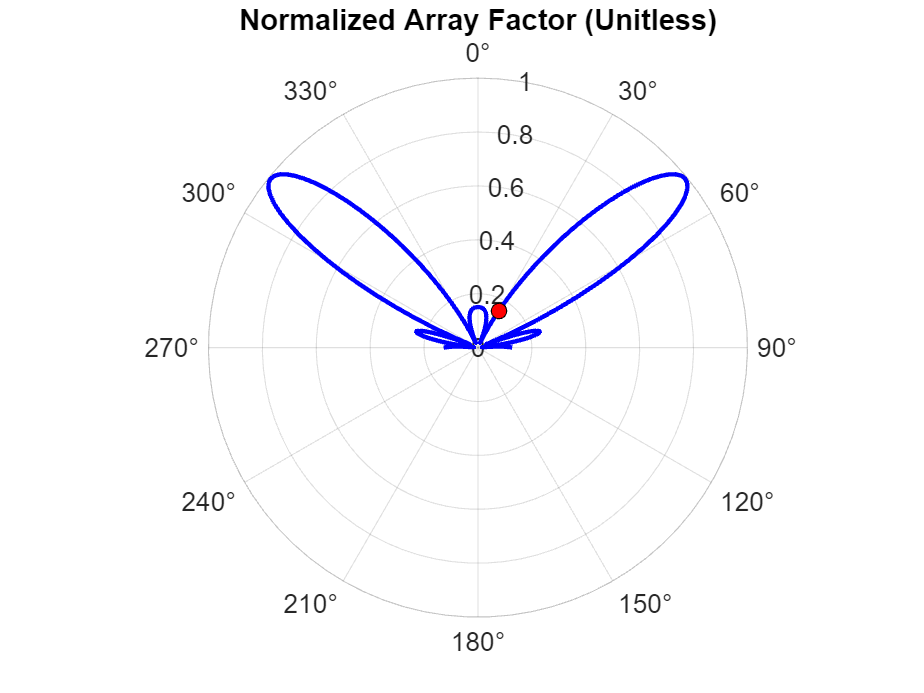

% fprintf('Simulated Expected Value: %.4f | Variance: %.6f\n', simulated_avg, var(simulated_average));
sim_sigma = sqrt(sim_var);
analytic_sigma = sqrt(analytic_var);

combined_mean = (sim_mean + analytic_mean)/2;
combined_sigma = (sim_sigma + analytic_sigma)/2;


x_axis = linspace(combined_mean - 3*combined_sigma, ...
                  combined_mean + 3*combined_sigma, 500);
% -------- FIGURE 1: Polar AF --------
fig1 = figure;
ax1 = polaraxes(fig1);
hold(ax1,'on')
polarplot(ax1, theta, abs(AF/N),'b','LineWidth',2);
polarplot(ax1, measure_angle_rad, abs(AF(measure_angle_deg + 90)/N), 'o', ...
    'MarkerSize',7,'MarkerFaceColor','r','MarkerEdgeColor','black');
ax1.ThetaZeroLocation = 'top';
ax1.ThetaDir = 'clockwise';
ax1.FontSize = 12;
title(ax1,'Normalized Array Factor (Unitless)');
grid(ax1,'on');

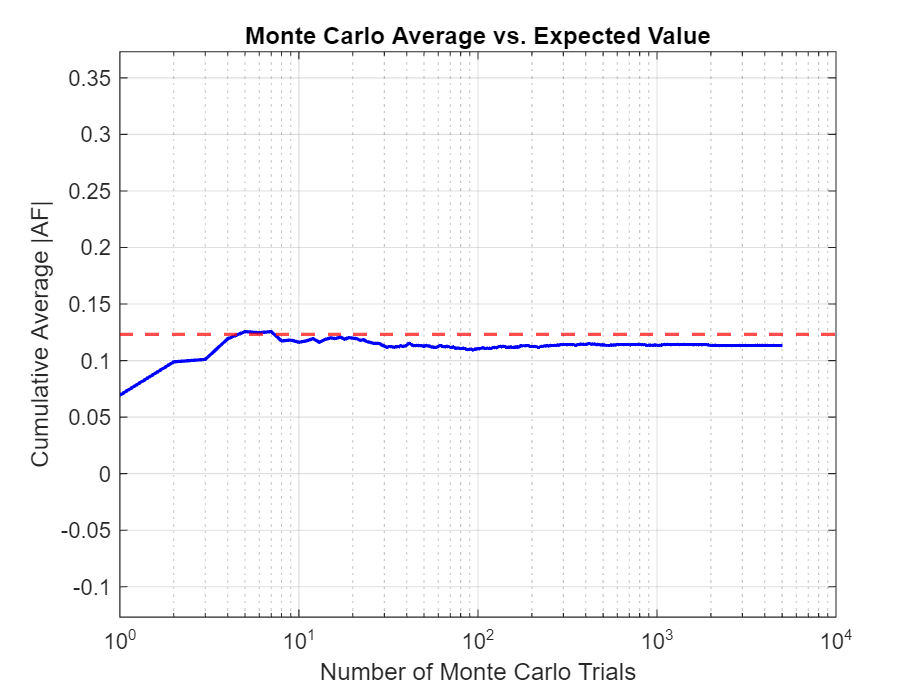


% -------- FIGURE 2: Monte Carlo Average --------
fig2 = figure;
ax2 = axes(fig2);
semilogx(ax2, 1:T, cumsum(abs(simulated_average))./(1:T)', 'b','LineWidth',1.5);
yline(ax2, analytic_mean,'r--','LineWidth',1.5);
xlabel(ax2,'Number of Monte Carlo Trials');
ylabel(ax2,'Cumulative Average |AF|');
title(ax2,'Monte Carlo Average vs. Expected Value');
grid(ax2,'on');
ylim(ax2,[analytic_mean - 0.25, analytic_mean + 0.25]);

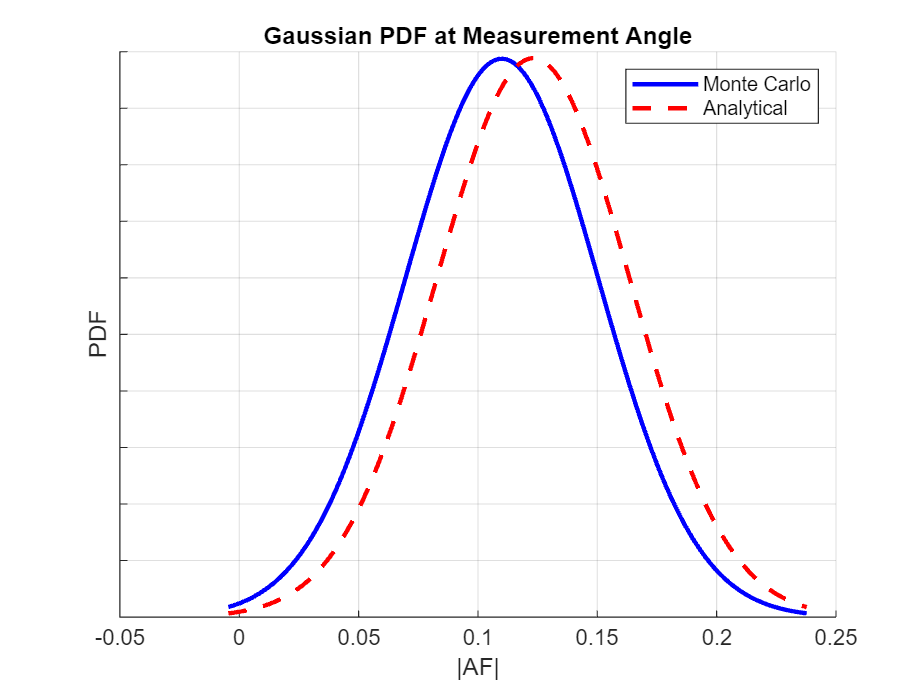



% -------- FIGURE 3: PDF --------
fig3 = figure;
ax3 = axes(fig3);
hold(ax3,'on')
plot(ax3, x_axis, normpdf(x_axis, sim_mean, sim_sigma),'b','LineWidth',2);
plot(ax3, x_axis, normpdf(x_axis, analytic_mean, analytic_sigma),'r--','LineWidth',2);
xlabel(ax3,'|AF|');
ylabel(ax3,'PDF');
title(ax3,'Gaussian PDF at Measurement Angle');
legend(ax3,'Monte Carlo','Analytical');
grid(ax3,'on');

set(ax3,'YTickLabel',[])   % remove y-axis numbers